Problema 1. rezolvarile sunt in fisier

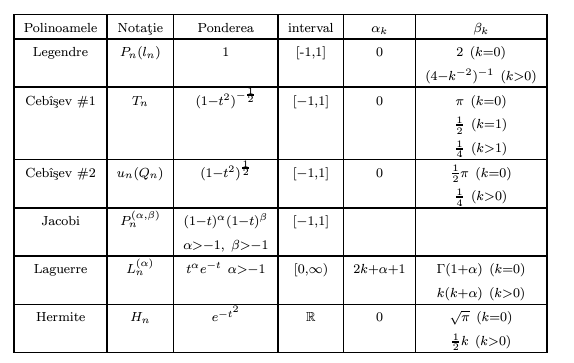

Problema 2. 

f = @(x)sin(x.^2);
g = @(x)cos(x.^2);
tolerance = 1e-7;

a = -1; 
b = 1; 
n0 = 5;

[g_nodes, g_coeff] = legendre(n0);
v1(1) = vquad(g_nodes, g_coeff, f);
v2(1) = vquad(g_nodes, g_coeff, g);
k = 1;

for n=n0+1:4*n0
    [gn, gc] = legendre(n);
    k = k + 1;
    v1(k) = vquad(gn, gc, f);
    if abs(v1(k) - v1(k - 1)) < tolerance
        disp('noduri:');
        disp(gn);
        disp('coeficienti:');
        disp(gc);
        fprintf('I1(%2d)=%10.6f\n',n,v1(k));
        break;
    end
end

noduri:


   -0.9603
   -0.7967
   -0.5255
   -0.1834
    0.1834
    0.5255
    0.7967
    0.9603



coeficienti:


    0.1012    0.2224    0.3137    0.3627    0.3627    0.3137    0.2224    0.1012



I1( 8)=  0.620537


k = 1;
for n=n0+1:4*n0
    [gn, gc] = legendre(n);
    k = k + 1;
    v2(k) = vquad(gn, gc, g);
    if abs(v2(k) - v2(k - 1)) < tolerance
        disp('noduri:');
        disp(gn);
        disp('coeficienti:');
        disp(gc);
        fprintf('I2(%2d)=%10.6f\n',n,v2(k));
        break;
    end
end

noduri:


   -0.9603
   -0.7967
   -0.5255
   -0.1834
    0.1834
    0.5255
    0.7967
    0.9603



coeficienti:


    0.1012    0.2224    0.3137    0.3627    0.3627    0.3137    0.2224    0.1012



I2( 8)=  1.809048


syms t rest f(t) xi
disp(vpa(int(sin(t^2),t,-1,1)));

$$0.62053660344676220361630484633079$$

disp(vpa(int(cos(t^2),t,-1,1)));

$$1.8090484758005441629495767336651$$

po = legendreP(n, t);
c = coeffs(po, 'All');
po = po/c(1)

$$po = t^{8}-\frac{28\,t^{6}}{15}+\frac{14\,t^{4}}{13}-\frac{28\,t^{2}}{143}+\frac{7}{1287}$$

rest=1/factorial(2*n)*int(po^2,t,-1,1)*subs(diff(f(t),t,n),t,xi);
[rest,vpa(rest)]

$$ans = \left(\begin{array}{cc} \frac{7573384136472607\,\frac{\partial^{8}}{\partial \xi^{8}}f\left(\xi \right)}{3404126326545748309514119859404800} & 0.000000000000000002224765889977270125691636407827\,\frac{\partial^{8}}{\partial \xi^{8}}f\left(\xi \right) \end{array}\right)$$

Problema 3. 

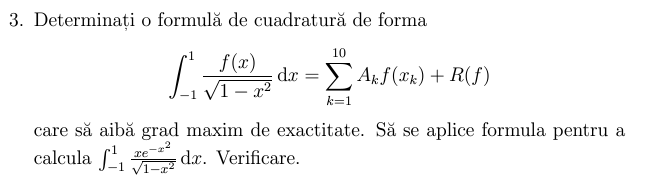

clear
f = @(x) x.*exp(-x.^2);
n = 10;
[gn, gc] = cebisev1(n);
vi = vquad(gn, gc, f)

vi = 8.3267e-17

I = @(x) x .* exp(-x.^2) ./ sqrt(1 - x.^2);
integral_exact = integral(f, -1, 1, 'RelTol', 1e-12, 'AbsTol', 1e-12);
fprintf('Valoarea exacta a integralei: %.10f\n', integral_exact);

Valoarea exacta a integralei: -0.0000000000


Problema 4. 

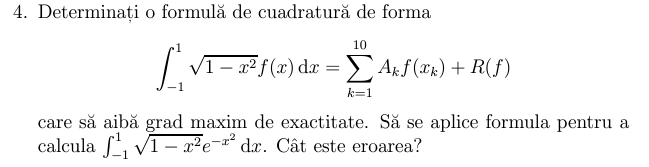

clear
f = @(x) exp(-x.^2);
n = 10;
[gn, gc] = cebisev2(n);
vi = vquad(gn, gc, f)

vi = 1.2589

exact_integral = integral(@(x) sqrt(1 - x.^2) .* exp(-x.^2), -1, 1, 'RelTol', 1e-12, 'AbsTol', 1e-12);
fprintf('Valoarea exacta a integralei: %.10f\n', exact_integral);

Valoarea exacta a integralei: 1.2589242566


error = abs(vi - exact_integral);
fprintf('Eroarea: %.10f\n', error);

Eroarea: 0.0000000000


Problema 5. 

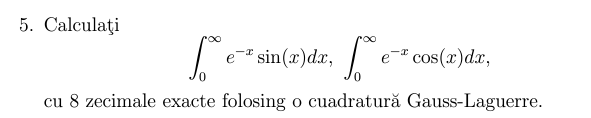

f = @(x) exp(-x) .* sin(x);
g = @(x) exp(-x) .* cos(x);
n = 10;

[gn, gc] = laguerre(n);
disp(gn);

    0.1378
    0.7295
    1.8083
    3.4014
    5.5525
    8.3302
   11.8438
   16.2793
   21.9966
   29.9207



disp(gc);

    0.3084    0.4011    0.2181    0.0621    0.0095    0.0008    0.0000    0.0000    0.0000    0.0000



vi_sin = vquad(gn, gc, f)

vi_sin = 0.2000

vi_cos = vquad(gn, gc, g)

vi_cos = 0.4000

fprintf('Approximation of the integral ∫ e^(-x) sin(x) dx: %.8f\n', vi_sin);

Approximation of the integral ∫ e^(-x) sin(x) dx: 0.20000019


fprintf('Approximation of the integral ∫ e^(-x) cos(x) dx: %.8f\n', vi_cos);

Approximation of the integral ∫ e^(-x) cos(x) dx: 0.40000029



tolerance = 1e-8;
pondere = @(x) exp(-x);
prev_f = 0;
prev_g = 0;
curr_f = 0;
curr_g = 0;
while true
    [gn, gc] = laguerre(n);
    curr_f = vquad(gn, gc, f);
    curr_g = vquad(gn, gc, g);
    error_f = abs(curr_f - prev_f);
    error_g = abs(curr_g - prev_g);
    if error_f < tolerance && error_g < tolerance
        disp(['Eroare pentru ∫ e^(-x) sin(x) dx: ', num2str(error_f)]);
        disp(['Eroare pentru ∫ e^(-x) cos(x) dx: ', num2str(error_g)]);
        break;
    end
    prev_f = curr_f;
    prev_g = curr_g;
    n = n + 1;
end

Eroare pentru ∫ e^(-x) sin(x) dx: 2.514e-09


Eroare pentru ∫ e^(-x) cos(x) dx: 1.238e-09


fprintf('Aproximatia finala pentru ∫ e^(-x) sin(x) dx: %.8f\n', curr_f);

Aproximatia finala pentru ∫ e^(-x) sin(x) dx: 0.20000000


fprintf('Aproximatia finala pentru ∫ e^(-x) cos(x) dx: %.8f\n', curr_g);

Aproximatia finala pentru ∫ e^(-x) cos(x) dx: 0.40000000


Problema 6. 

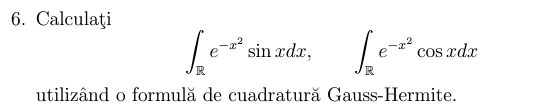

clear
f = @(x) exp(-x.^2) .* sin(x);
g = @(x) exp(-x.^2) .* cos(x);

n = 10;
[gn, gc] = hermite(n);
vi_f = vquad(gn, gc, f)

vi_f = -1.8721e-16

vi_g = vquad(gn, gc, g)

vi_g = 1.1059

Problema 7.

clear
syms t u

ve = vpa(int(1 / sqrt(sin(t)), t, sym(0), sym(pi) / sym(2)))

$$ve = 2.6220575542921198104648395898911$$

ved = double(ve)

ved = 2.6221

integral = int(1 / sqrt(sin(t)), t, 0, sym(pi) / sym(2), 'Hold', true)

$$integral = \int_{0}^{\frac{\pi }{2}}\frac{1}{\sqrt{\sin\left(t\right)}}\mathrm{d}t$$

changeIntegrationVariable(integral, t, asin((u + 1) / 2))

$$ans = \int_{-1}^{1}\frac{1}{2\,\sqrt{\frac{u}{2}+\frac{1}{2}}\,\sqrt{1-{\left(\frac{u}{2}+\frac{1}{2}\right)}^{2}}}\mathrm{d}u$$


f = @(x) sqrt(2) ./ (sqrt(x + 3));
n0 = 10;
a = -1/2;
b = -1/2;
tolerance = 1e-9;

[gn, gc] = jacobi2(n0, a, b);
vi(1) = vquad(gn, gc, f);

k = 1;
for n = n0+1:10*n0
    k = k + 1;
    [gn, gc] = jacobi2(n, a, b);
    vi(k) = vquad(gn, gc, f);
    if (abs(vi(k) - ved) < tolerance) || n > 1000
        fprintf('vi(%d)=%11.9f\n', n, vi(k));
        break;
    end
end

vi(11)=2.622057554



n, vi(k)

n = 11

ans = 2.6221